% 使用自定义核训练 SVM 分类器
% 此示例说明如何使用自定义核函数（例如 sigmoid 核）训练 SVM 分类器，
% 并调整自定义核函数参数。

## 导入数据

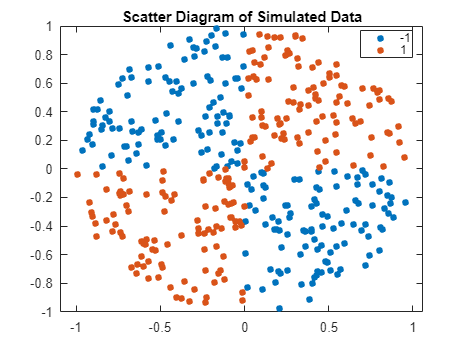

clear
SVM_Data1

## 使用 sigmoid 核函数训练 SVM 分类器。标准化数据是一种良好的做法。

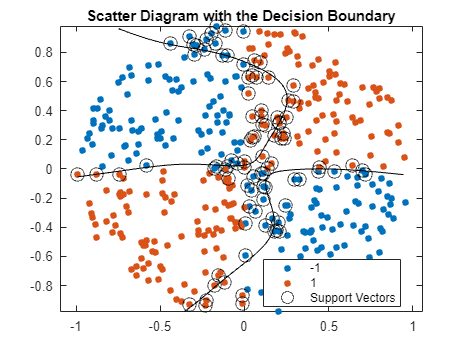

Mdl1 = fitcsvm(X,Y,'KernelFunction','mysigmoid','Standardize',true);
% Mdl1 是 ClassificationSVM 分类器，其中包含估计的参数。
% 绘制数据，并确定支持向量和决策边界。

% Compute the scores over a grid
d = 0.02; % Step size of the grid
[x1Grid,x2Grid] = meshgrid(min(X(:,1)):d:max(X(:,1)),...
    min(X(:,2)):d:max(X(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];        % The grid
[~,scores1] = predict(Mdl1,xGrid); % The scores

figure;
h(1:2) = gscatter(X(:,1),X(:,2),Y);
hold on
h(3) = plot(X(Mdl1.IsSupportVector,1),...
    X(Mdl1.IsSupportVector,2),'ko','MarkerSize',10);
% Support vectors
contour(x1Grid,x2Grid,reshape(scores1(:,2),size(x1Grid)),[0 0],'k');
% Decision boundary
title('Scatter Diagram with the Decision Boundary')
legend({'-1','1','Support Vectors'},'Location','Best');
hold off



% 您可以调整核参数，尝试改进决策边界的形状。这也可能降低样本内的误分类率，
% 但您应首先确定样本外的误分类率。
% 使用 10 折交叉验证确定样本外的误分类率。
CVMdl1 = crossval(Mdl1);
misclass1 = kfoldLoss(CVMdl1)

misclass1 = 0.1350

% misclass1 =    0.1350
% 样本外的误分类率为 13.5%。